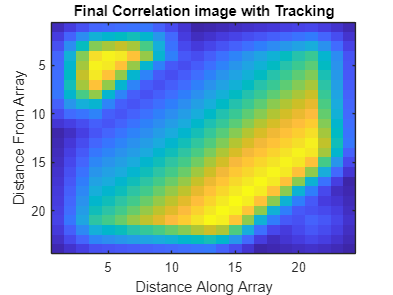

%Test 1: sample images

load testPersist.mat -mat
raw_data = magic(25)./max(magic(25));
% raw_data = persist_image;


template = ones(4,4);
offset = 2;

%trim data to avoid edge case
data = raw_data(1+offset:end-offset,1+offset:end-offset);

%performs correlation
c = xcorr2(data, template);

% Find the maximum value and its linear index
[maxValue, linearIndex] = max(c(:));

% Convert linear index to row and column indices
[row, col] = ind2sub(size(c), linearIndex);


figure(28)
imagesc(c)
title('Final Correlation image with Tracking');
xlabel('Distance Along Array');
ylabel('Distance From Array');

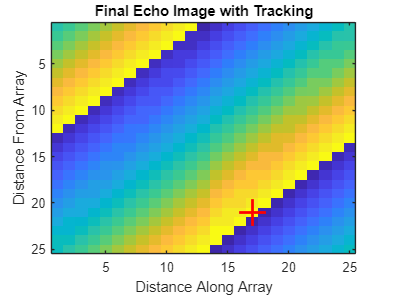



%plot image
figure(28)
imagesc(raw_data)
title('Final Echo Image with Tracking');
xlabel('Distance Along Array');
ylabel('Distance From Array');


%overlays onto figure(27)
hold on;
% x over target
plot(col+offset, row+offset, '+', 'MarkerSize',20, 'LineWidth', 2, 'Color', 'red')
% circle over target
%     plot(track_col, track_row, 'o', 'MarkerSize',50, 'LineWidth', 2, 'Color', 'red')
hold off;

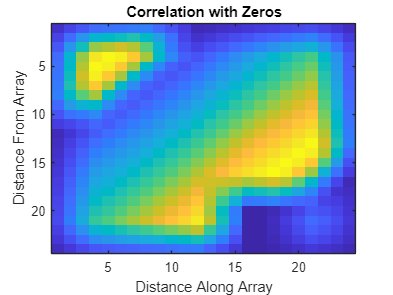


%remove max values for second target tracking
data(row-offset:row+offset, col-offset:col+offset) = 0;

%performs correlation
c = xcorr2(data, template);

% Find the maximum value and its linear index
[maxValue, linearIndex] = max(c(:));

% Convert linear index to row and column indices
[row, col] = ind2sub(size(c), linearIndex);


imagesc(c)
title('Correlation with Zeros');
xlabel('Distance Along Array');
ylabel('Distance From Array');






%overlays onto figure(27)
% hold on;
% % x over target
% plot(col+offset, row+offset, 'x', 'MarkerSize',20, 'LineWidth', 2, 'Color', 'red')
% % circle over target
% %     plot(track_col, track_row, 'o', 'MarkerSize',50, 'LineWidth', 2, 'Color', 'red')
% hold off;

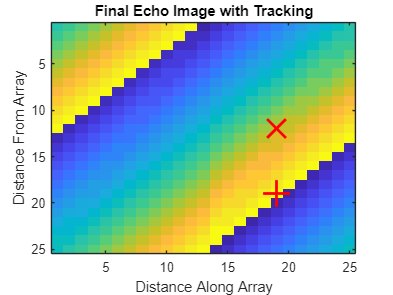


raw_data = magic(25)./max(magic(25));



template = ones(4,4);
offset = 6;

%trim data to avoid edge case
data = raw_data(1+offset:end-offset,1+offset:end-offset);

%performs correlation
[row, col] = tracking(data, template);

%plot image
figure(28)
imagesc(raw_data)
title('Final Echo Image with Tracking');
xlabel('Distance Along Array');
ylabel('Distance From Array');

%overlays onto figure(27)
hold on;
% x over target
plot(col+offset, row+offset, '+', 'MarkerSize',20, 'LineWidth', 2, 'Color', 'red')
% circle over target
%     plot(track_col, track_row, 'o', 'MarkerSize',50, 'LineWidth', 2, 'Color', 'red')
hold off;

%remove max values for second target tracking
data(row-offset:row+offset, col-offset:col+offset) = 0;


[row, col] = tracking(data, template);


%overlays onto figure(27)
hold on;
% x over target
plot(col+offset, row+offset, 'x', 'MarkerSize',20, 'LineWidth', 2, 'Color', 'red')
% circle over target
%     plot(track_col, track_row, 'o', 'MarkerSize',50, 'LineWidth', 2, 'Color', 'red')
hold off;

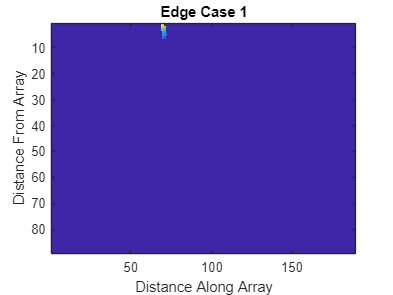

%Test 2 edge cases

load trackingTestImages.mat -mat
raw_data = image;



template = ones(4,4);
offset = 6;

%trim data to avoid edge case
data = raw_data(1+offset:end-offset,1+offset:end-offset);

imagesc(data)
title('Edge Case 1');
xlabel('Distance Along Array');
ylabel('Distance From Array');

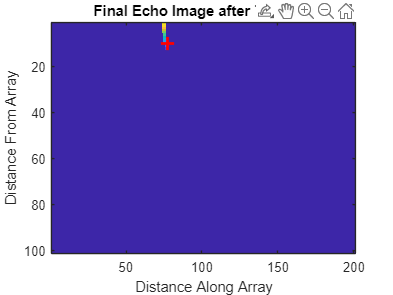


%performs correlation
[row, col] = tracking(data, template);

%plot image
figure(28)
imagesc(raw_data)
title('Final Echo Image after Tracking');
xlabel('Distance Along Array');
ylabel('Distance From Array');

%overlays onto figure(27)
hold on;
% x over target
plot(col+offset, row+offset, '+', 'MarkerSize',10, 'LineWidth', 2, 'Color', 'red')
% circle over target
%     plot(track_col, track_row, 'o', 'MarkerSize',50, 'LineWidth', 2, 'Color', 'red')
hold off;


%remove max values for second target tracking
data(abs(row-offset):row+offset, abs(col-offset):col+offset) = 0;

% 
% [row, col] = tracking(data, template);
% 
% 
% %overlays onto figure(27)
% hold on;
% % x over target
% plot(col+offset, row+offset, '+', 'MarkerSize',20, 'LineWidth', 2, 'Color', 'red')
% % circle over target
% %     plot(track_col, track_row, 'o', 'MarkerSize',50, 'LineWidth', 2, 'Color', 'red')
% hold off;
